n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 5;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

p=3000

p = 3000

sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
    
        
x_noiseless = [ mu_1_mat ; mu_2_mat ];

e=eig(x_noiseless*x_noiseless');
e_sorted = -sort(-e);

e_sorted = 1.0e+03 *

    1.2500
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000





x_noisy = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
H = x_noisy * x_noisy';
size(H)

ans =    200   200


[V,D] = eig(H);
[d,ind] = sort(diag(D), "descend");
Ds = D(ind,ind);

Ds = 1.0e+03 *

    4.9122         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    4.7413         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Vs = V(:,ind);

Vs =     0.0622    0.0258   -0.0950    0.0338    0.0617   -0.0446   -0.0546    0.0448   -0.0273   -0.0902    0.0734   -0.0473    0.0054    0.0176   -0.0493   -0.0843   -0.1083   -0.0344    0.0059    0.0516   -0.1859    0.0231   -0.0162   -0.0337    0.0832    0.0367   -0.0071    0.0350    0.0035    0.0307    0.0587    0.0502   -0.1074    0.0640   -0.0095    0.1264   -0.0474    0.0514    0.0565    0.0349   -0.0759   -0.1064    0.0748    0.0335   -0.0017    0.0217    0.1048   -0.1129   -0.0667    0.0239
    0.0722    0.0379    0.0529    0.0302    0.0110   -0.0544   -0.0528    0.0305    0.0437    0.0620    0.0568   -0.0033    0.0447    0.0112    0.0113   -0.1046    0.0856    0.1122   -0.0374   -0.0830    0.0272    0.0310   -0.1002    0.1012    0.0764   -0.0963   -0.0228   -0.0609    0.0748    0.1012    0.0920   -0.0520    0.0100    0.1772   -0.0211   -0.0076   -0.0865    0.1435   -0.0927    0.0317   -0.0025    0.0016    0.1011   -0.1146   -0.0254   -0.0604   -0.0465   -0.0576    0.1211   -



eigenval_vec = diag(D,0)

eigenval_vec = 1.0e+03 *

    1.7019
    1.7191
    1.7389
    1.7503
    1.7620
    1.7918
    1.8013
    1.8099
    1.8403
    1.8528


eigenval_vec_sorted= -sort(-eigenval_vec)

eigenval_vec_sorted = 1.0e+03 *

    4.9122
    4.7413
    4.6020
    4.5465
    4.5234
    4.4829
    4.4383
    4.4187
    4.3820
    4.3669


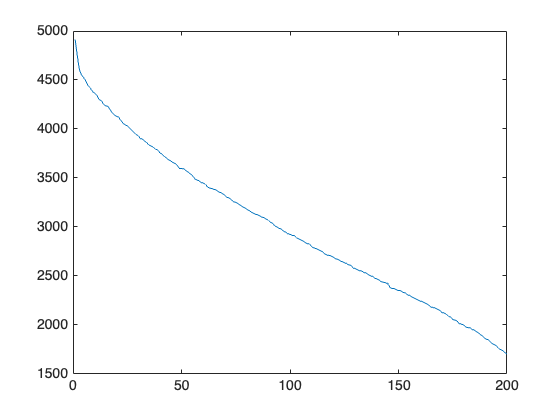

plot(eigenval_vec_sorted)

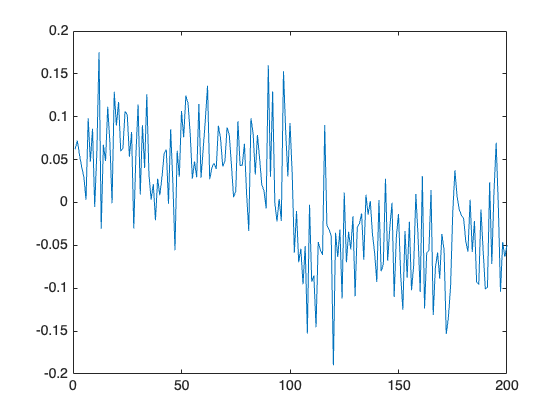

plot(Vs(:,1))